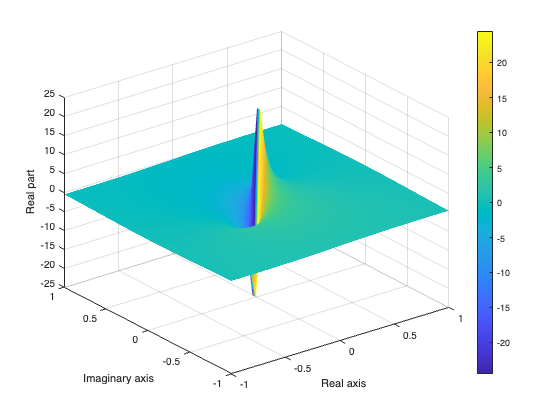

% Define the complex function
f = @(z) log10(z);

% Define the range of the domain to plot
xmin = -1; xmax = 1;
ymin = -1; ymax = 1;

% Define the meshgrid of the domain
npoints = 50;
[x, y] = meshgrid(linspace(xmin, xmax, npoints), linspace(ymin, ymax, npoints));
z = x + 1i*y;

% Evaluate the function on the meshgrid
w = f(z);

% Create the Riemann surface plot
figure;
surf(real(z), imag(z), real(w), imag(w), 'EdgeColor', 'none', 'FaceColor', 'interp');
xlabel('Real axis');
ylabel('Imaginary axis');
zlabel('Real part');
colorbar;